# Kannada Alphabets

org = imread('alphas3.jpg');
org_bw = im2bw(org);
[M N] = size(org_bw);
ind = 1;
for j = 1:10
    for i = 1:5
        img1 = org_bw(((i-1)*M/5)+1:i*M/5,((j-1)*N/10)+1:(j*N/10));
        im_comp = imcomplement(img1);
        im_final = imresize(im_comp,[28 28]);
        subplot(5,10,ind)
        imshow(im_final)
        ind = ind+1;
    end
end 

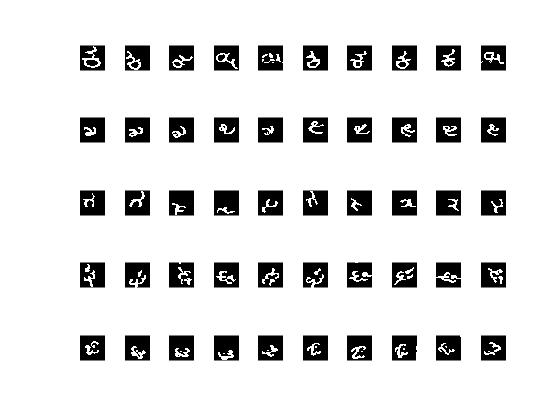

saveas(gcf,"alphaproccessed.jpg")